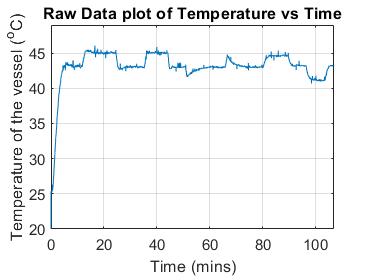

clear
clc
clf
data = load('B6A_Closed.txt');
n = (length(data));
time = data(1:n,1);
setpoint = data(1:n,2);
output  = data(1:n,3);
heater = data(1:n,4);
flow = data(1:n,5);
dU = 1.6;
U=12;

time = time/60; %in mins
figure(1)
plot(time, output);
xlabel('Time (mins)')
ylabel('Temperature of the vessel (^oC)')
ylim([20 49])
title('Raw Data plot of Temperature vs Time')
grid on


% requires signal processing toolbox
%out_filtered = medfilt1(output,10);
%out_filtered(1) =  out_filtered(2);
%plot(time,out_filtered,LineWidth=2)
%hold off
%legend('Raw','Processed')

%plot(time,out_filtered,LineWidth=2);
%title("Filtered Temperature output vs Time");
%grid on;
%xlabel("Time(min)");
%ylabel("Temperature(^oC)");


#### Our Controllers

K_p = 1.3903

K_p = 1.3903

tau_p = 148.477/60 % in mins

tau_p = 2.4746


K_d = -5.3340

K_d = -5.3340

tau_d = 215.9037/60 % in mins

tau_d = 3.5984


PI1_K = 1.7550

PI1_K = 1.7550

PI1_tau = 78.3744/60 % in mins

PI1_tau = 1.3062


PI2_K = 3.0230

PI2_K = 3.0230

PI2_tau = 135.0030/60 % in mins

PI2_tau = 2.2501


P2_K = 1.868

P2_K = 1.8680

Important for calculations

A = [-1/tau_p 0;
    0 -1/tau_d];

B = [K_p/tau_p 0;
    0 K_d/tau_d];

C = [1 1];

#### Servo Response of PI 1

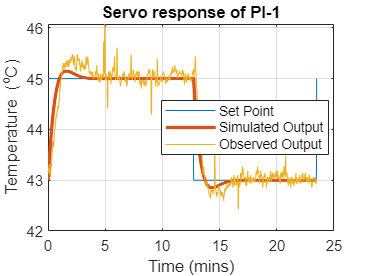

begin1 = find(setpoint==45,1);
end1 = find(setpoint == 45 & time>30,1);
t1 = time(begin1:end1) - time(begin1);
SP = 43;
l1 = length(t1);
x1 = zeros(l1,2);

del_y1 = zeros(l1,1);
del_u1 = zeros(l1,1);
e1 = zeros(l1,1);
z1 = zeros(l1,1);

del_SP1 = setpoint(begin1:end1) - SP;%cm
d1 = 12; %in amp
del_d1 = flow(begin1:end1) - d1;

for k = 1:(l1-1)
del_y1(k) = C*(x1(k,:)');
e1(k) = del_SP1(k) - del_y1(k);
del_u1(k) = PI1_K*e1(k) + (PI1_K/PI1_tau)*z1(k);
h = t1(k+1) - time(k);
v = [del_u1(k);
    del_d1(k)];
x1(k+1,:) = ((eye(2)+h*A)*(x1(k,:))' + (h*B*v))';
z1(k+1) = z1(k) + h*e1(k);
end

figure(2)
plot(t1,del_SP1+SP);
hold on;
grid on;
plot(t1,del_y1+SP,LineWidth=2);
dfs = output(begin1:end1);
plot(t1,dfs);
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title('Servo response of PI-1');
legend("Set Point ", "Simulated Output ", "Observed Output",Location="best");
hold off;

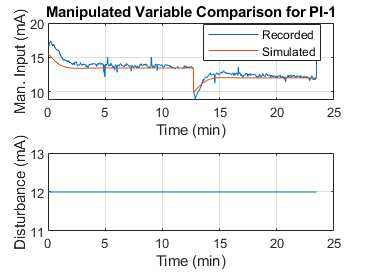


% Manipulated variable
subplot(2,1,1)
plot(t1,heater(begin1:end1))
title("Manipulated Variable Comparison for PI-1");
hold on;
grid on;
plot(t1,del_u1 + U);
xlabel("Time (min)")
ylabel("Man. Input (mA)")
legend("Recorded","Simulated",Location="best")
hold off;
subplot(2,1,2)
plot(t1,flow(begin1:end1))
ylabel("Disturbance (mA)");
grid on;
xlabel("Time (min)")

#### Servo Response of PI 2

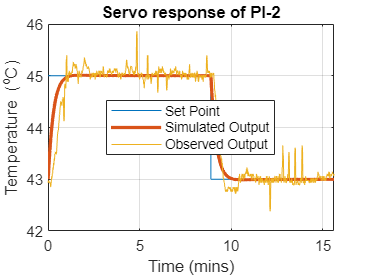

begin2 = find(setpoint==45 & time>30,1);
end2 = find(flow==13.6,1);
t2 = time(begin2:end2) - time(begin2);
SP = 43;
l2 = length(t2);
x2 = zeros(l2,2);

del_y2 = zeros(l2,1);
del_u2 = zeros(l2,1);
e2 = zeros(l2,1);
z2 = zeros(l2,1);

del_SP2 = setpoint(begin2:end2) - SP;%cm
d2 = 12; %in amp
del_d2 = flow(begin2:end2) - d2;

for k = 1:(l2-1)
del_y2(k) = C*(x2(k,:)');
e2(k) = del_SP2(k) - del_y2(k);
del_u2(k) = PI2_K*e2(k) + (PI2_K/PI2_tau)*z2(k);
h = t2(k+1) - time(k);
v = [del_u2(k);
    del_d2(k)];
x2(k+1,:) = ((eye(2)+h*A)*(x2(k,:))' + (h*B*v))';
z2(k+1) = z2(k) + h*e2(k);
end

figure(3)
plot(t2,del_SP2+SP);
grid on; hold on;
plot(t2,del_y2+SP,LineWidth=2);
plot(t2,output(begin2:end2));
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title('Servo response of PI-2')
legend("Set Point ", "Simulated Output ", "Observed Output",Location="best")
hold off

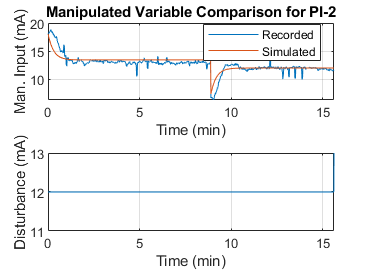


% Manipulated variable
subplot(2,1,1)
plot(t2,heater(begin2:end2))
title("Manipulated Variable Comparison for PI-2");
hold on;
grid on;
plot(t2,del_u2 + U);
xlabel("Time (min)")
ylabel("Man. Input (mA)")
legend("Recorded","Simulated",Location="best")
hold off;
subplot(2,1,2)
plot(t2,flow(begin2:end2))
ylabel("Disturbance (mA)");
ylim([11 13])
grid on;
xlabel("Time (min)")

#### Regulatory Response for PI-2

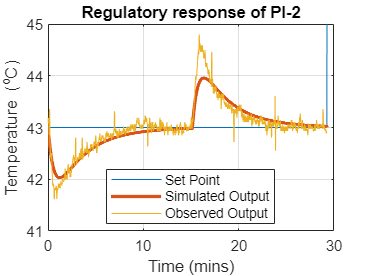

begin3 = find(flow == 13.6,1);
end3 = find(setpoint==45 & time>75,1);
t3 = time(begin3:end3) - time(begin3);
SP = 43;
l3 = length(t3);
x3 = zeros(l3,2);

del_y3 = zeros(l3,1);
del_u3 = zeros(l3,1);
e3 = zeros(l3,1);
z3 = zeros(l3,1);

del_SP3 = setpoint(begin3:end3) - SP;%cm
d3 = 12; %in amp
del_d3 = flow(begin3:end3) - d3;

for k = 1:(l3-1)
del_y3(k) = C*(x3(k,:)');
e3(k) = del_SP3(k) - del_y3(k);
del_u3(k) = PI2_K*e3(k) + (PI2_K/PI2_tau)*z3(k);
h = time(k+1) - time(k);
v = [del_u3(k);
    del_d3(k)];
x3(k+1,:) = ((eye(2)+h*A)*(x3(k,:))' + (h*B*v))';
z3(k+1) = z3(k) + h*e3(k);
end

figure(4)
plot(t3,del_SP3+SP);
grid on; hold on;
plot(t3,del_y3+SP,LineWidth=2);
plot(t3,output(begin3:end3));
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title('Regulatory response of PI-2')
legend("Set Point ", "Simulated Output ", "Observed Output",Location="best")
hold off

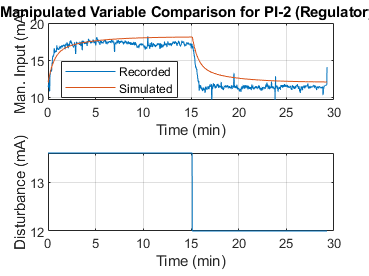


% Manipulated variable
subplot(2,1,1)
plot(t3,heater(begin3:end3))
title("Manipulated Variable Comparison for PI-2 (Regulatory)");
hold on;
grid on;
plot(t3,del_u3 + U);
xlabel("Time (min)")
ylabel("Man. Input (mA)")
legend("Recorded","Simulated",Location="best")
hold off;
subplot(2,1,2)
plot(t3,flow(begin3:end3))
ylabel("Disturbance (mA)");
grid on;
xlabel("Time (min)")

#### Servo of P2 controller

end4 = find(flow == 13.6 & time>85,1)

end4 = 5713

begin4 = find(setpoint==45 & time>75,1)

begin4 = 4746

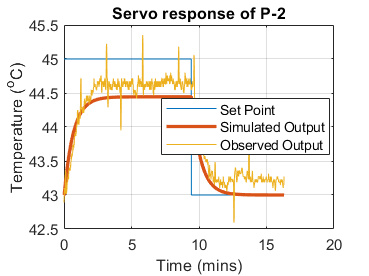

t4 = time(begin4:end4) - time(begin4);
SP = 43;
l4 = length(t4);
x4 = zeros(l4,2);

P2_tau = inf;

del_y4 = zeros(l4,1);
del_u4 = zeros(l4,1);
e4 = zeros(l4,1);
z4 = zeros(l4,1);

del_SP4 = setpoint(begin4:end4) - SP;%cm
d4 = 12; %in amp
del_d4 = flow(begin4:end4) - d4;

for k = 1:(l4-1)
del_y4(k) = C*(x4(k,:)');
e4(k) = del_SP4(k) - del_y4(k);
del_u4(k) = P2_K*e4(k) + (P2_K/P2_tau)*z4(k);
h = time(k+1) - time(k);
v = [del_u4(k);
    del_d4(k)];
x4(k+1,:) = ((eye(2)+h*A)*(x4(k,:))' + (h*B*v))';
z4(k+1) = z4(k) + h*e4(k);
end

figure(5)
plot(t4,del_SP4+SP);
grid on; hold on;
plot(t4,del_y4+SP,LineWidth=2);
plot(t4,output(begin4:end4));
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title('Servo response of P-2')
legend("Set Point ", "Simulated Output ", "Observed Output",Location="best")
hold off

#### Regulatory of P2 controller

begin5 = find(flow == 13.6 & time>85,1)

begin5 = 5713

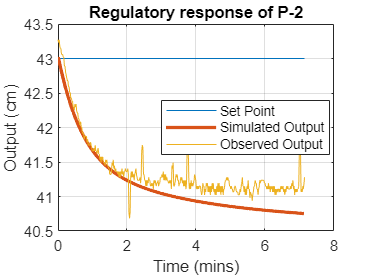

end5 = find(flow==12 & time>100,1);
t5 = time(begin5:end5) - time(begin5);
SP = 43;
l5 = length(t5);
x5 = zeros(l5,2);

P2_tau = inf;

del_y5 = zeros(l5,1);
del_u5 = zeros(l5,1);
e5 = zeros(l5,1);
z5 = zeros(l5,1);

del_SP5 = setpoint(begin5:end5) - SP;%cm
d5 = 12; %in amp
del_d5 = flow(begin5:end5) - d5;

for k = 1:(l5-1)
del_y5(k) = C*(x5(k,:)');
e5(k) = del_SP5(k) - del_y5(k);
del_u5(k) = P2_K*e5(k) + (P2_K/P2_tau)*z5(k);
h = time(k+1) - time(k);
v = [del_u5(k);
    del_d5(k)];
x5(k+1,:) = ((eye(2)+h*A)*(x5(k,:))' + (h*B*v))';
z5(k+1) = z5(k) + h*e5(k);
end

figure(6)
plot(t5,del_SP5+SP);
grid on; hold on;
plot(t5(1:end-1),del_y5(1:end-1)+SP,LineWidth=2);
plot(t5,output(begin5:end5));
xlabel('Time (mins)');
ylabel('Output (cm)');
title('Regulatory response of P-2')
legend("Set Point ", "Simulated Output ", "Observed Output",Location="best")
hold off

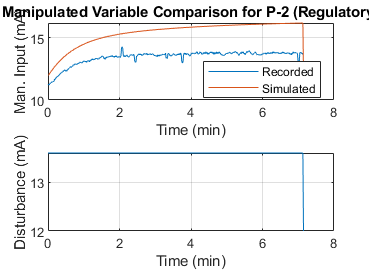



% Manipulated variable
subplot(2,1,1)
plot(t5,heater(begin5:end5))
title("Manipulated Variable Comparison for P-2 (Regulatory)");
hold on;
grid on;
plot(t5,del_u5 + U);
xlabel("Time (min)")
ylabel("Man. Input (mA)")
legend("Recorded","Simulated",Location="best")
hold off;
subplot(2,1,2)
plot(t5,flow(begin5:end5))
ylabel("Disturbance (mA)");
grid on;
xlabel("Time (min)")

#### Combined Graphs

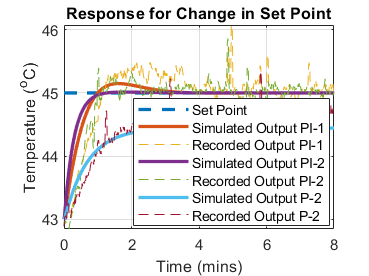

% All responses
figure(10)
plot(t1,del_SP1+SP,'--',LineWidth=2);
hold on;
grid on;
plot(t1,del_y1+SP,LineWidth=2);
plot(t1,output(begin1:end1),'--');
plot(t2,del_y2+SP,LineWidth=2);
plot(t2,output(begin2:end2),'--');
plot(t4,del_y4+SP,LineWidth=2);
plot(t4,output(begin4:end4),'--');
xlim([0,8])
legend("Set Point","Simulated Output PI-1","Recorded Output PI-1","Simulated Output PI-2","Recorded Output PI-2","Simulated Output P-2","Recorded Output P-2",Location="best")
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title("Response for Change in Set Point")
hold off;

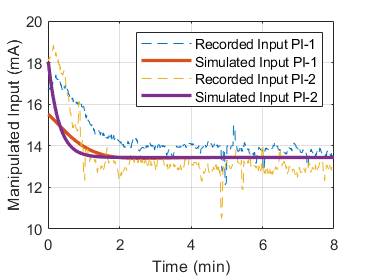


%Manipulated Inputs
figure(11)
plot(t1,heater(begin1:end1),'--')
hold on;
grid on;
plot(t1,del_u1 + U,LineWidth=2);
plot(t2,heater(begin2:end2),'--')
plot(t2,del_u2 + U,LineWidth=2);
xlabel("Time (min)")
ylabel("Manipulated Input (mA)")
xlim([0,8])
legend("Recorded Input PI-1","Simulated Input PI-1","Recorded Input PI-2","Simulated Input PI-2")
hold off

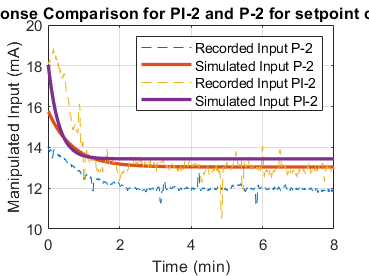



%Manipulated Inputs
figure(15)
plot(t4,heater(begin4:end4),'--')
title("Response Comparison for PI-2 and P-2 for setpoint change")
hold on;
grid on;
plot(t4,del_u4 + U,LineWidth=2);
plot(t2,heater(begin2:end2),'--')
plot(t2,del_u2 + U,LineWidth=2);
xlabel("Time (min)")
ylabel("Manipulated Input (mA)")
xlim([0,8])
legend("Recorded Input P-2","Simulated Input P-2","Recorded Input PI-2","Simulated Input PI-2")
hold off

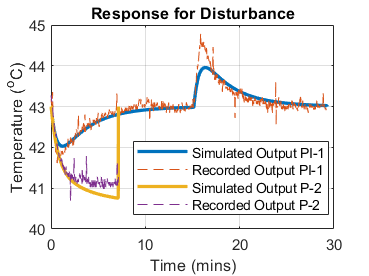


% Regulation for PI2 and P-2
figure(12)
plot(t3,del_y3+SP,LineWidth=2);
hold on;
grid on;
plot(t3,output(begin3:end3),'--');
plot(t5,del_y5+SP,LineWidth=2);
plot(t5,output(begin5:end5),'--');
legend("Simulated Output PI-1","Recorded Output PI-1","Simulated Output P-2","Recorded Output P-2",Location="best")
xlabel('Time (mins)');
ylabel('Temperature (^oC)');
title("Response for Disturbance")
hold off;

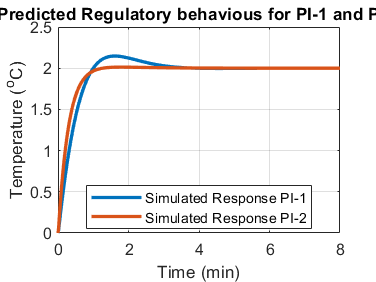



% Simulation PI-1 and PI-2
figure(14)
plot(t1,del_y1 ,LineWidth=2);

hold on;
grid on;
plot(t2,del_y2,LineWidth=2);
xlabel("Time (min)")
ylabel("Temperature (^oC)")
xlim([0,8])
title("Predicted Regulatory behavious for PI-1 and PI-2")
legend("Simulated Response PI-1","Simulated Response PI-2",Location="best")
hold off